# Collaborative forecasting using  Vertical Asynchronous Federated Learning  and a Multilayer Perceptron (FMLP) followed by a Kalman Filter (KF) and 

Collaborative forecasting was implemented in the context of Predictive Maintenance (PdM) in which the maintenance process of machinery is improved by estimating its Remaining Useful Time (RUL). In this work, the RUL estimation of Turbofan Engines is assessed using FD004 sets of C-MPASS datasets. 

This collaborative forecasting problem considers that multiple Condition Monitoring Systems (CMSs) parallely monitor the health degradation of turbofans. The algorithm chosen to solve this problem is Vertical Asynchronous Federated Learning. This algorithm allows parties' models learn from each others by considering that parties' datasets share the same samples indexes but may differ in input feature space.

Turbofan engines have been monitored using 24 fields, 21 sensor signals and 3 settings (Altitude, Throtle Resolve and Mach Number). A subgroup of 16 sensors have been represented the health degradation of turbofans:

- [2, 3, 4, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 17, 20, 21]

Thirteen of these signals are randomly chosen and distributed to four parties to construct the Federated scenario with a vertical data partititing approach. 

The Machine Learning architecture used to estimate the RUL at each party corresponds to a  Multilayer Perceptron (MLP) followed by a Kalman Filter (KF). To train MLP-KF, the following data pre-processing steps and hyperparameters were considered: 

The data was pre-processed following the procedures described in [https://doi.org/10.36001/phme.2020.v5i1.1228](https://doi.org/10.36001/phme.2020.v5i1.1228) 

The groud truth described by  the RUL field describes a piecewise degradation curve with an elbow point =120. 

To Run this example, the following tools have to be installed: 

-  Parallel Computing

- Deep Learning Toolbox

## Set Up Parallel Environment

Create a parallel pool with 4 workers (4 nodes). 

clear
pool = parpool('local',4);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


numWorkers=pool.NumWorkers;

## Load Data Set

All data used in this example is initially stored in a centralized location. To make this data highly non-IID,we  distributed the data among the nodes. The percentage of Testing ang Validation data  under each node corresponds to 80% and 20%, respectively.

Specify the folder containing the image data. 

FD00X=4; %
sensorsCMAPSS=21;
trainingDatastore = parquetread(fullfile(pwd,strcat("train_fd00",num2str(FD00X),".parquet")));
%trainingDatastore.id=[];
trainingDatastore.cycle=[];
trainingDatastore.setting1=[];
trainingDatastore.setting2=[];
trainingDatastore.setting3=[];

## Training and Evaluation data

The data is distributed among the workers according to the following configuration settings:

Train=80% of TrainFD004

Evaluation=20% of TrainFD004

%rng('default') % Fix random seed for reproducibility

% All parties differ in input space
featureType={[2,3,4,6,7,8,9,10,13,15,17,20,21],[2,4,7,8,9,11,12,13,14,15,17,20,21],[2,3,4,7,8,10,11,12,13,15,17,20,21],[2,4,6,7,8,9,10,12,13,14,17,20,21]};

groundTruthIndex=sensorsCMAPSS+1;

evalDataOfNodes=trainingDatastore(trainingDatastore.id>211, 2:sensorsCMAPSS+2);
trainingDatastore=trainingDatastore(trainingDatastore.id<=211, 2:sensorsCMAPSS+2);
numObservationsTraining=size(trainingDatastore,1);
indexes=randperm(numObservationsTraining);
trainDataOfNodes=trainingDatastore(indexes,:);


trainDataOfNodes=trainDataOfNodes{:,1:sensorsCMAPSS+1};
evalDataOfNodes=evalDataOfNodes{:,1:sensorsCMAPSS+1};


## Collecting evaluation data

XVal=evalDataOfNodes(:,1:sensorsCMAPSS)';
YVal=evalDataOfNodes(:,groundTruthIndex)';

## Define the Nerwork and Initialize Prediction Matrix

Create a network (Multi-Layer Perceptron).



N1=10;                  % Middle Layer Neurons
N2=1;                   % Output Layer Neurons     
w1={};
w2={};
b1={};
b2={};

change1={};
changeB1={};
change2={};
changeB2={};

SGDWithMomentum=false;
numObservationsTraining=size(trainDataOfNodes,1); %Number of observations
% Prediction matrix A (n,m)
% n number of observations
% m number of nodes
% idx = randperm(length(trainDataOfNodes));
% trainDataOfNodes=trainDataOfNodes(idx,:)
idx = 1:(numObservationsTraining);

spmd
    
    rng(4) % Fix random seed for reproducibility 
    
    % Initialization of weights
    %Input Layer takes different nodes, depending on the worker settings
    w1{labindex}=(randn(N1,size(featureType{labindex},2)));    %  Input Layer Neurons (feature length)
    b1{labindex}=(randn(N1,1));

    w2{labindex}=(randn(N2,N1));    % Initial weights of middle and output layer connections
    b2{labindex}=(randn(N2,1));
    % forward
    X=trainDataOfNodes(idx,featureType{labindex})';
    Y=trainDataOfNodes(idx,groundTruthIndex);
    [z1,a1,z2,a2] = forward(X,w1{labindex},w2{labindex},b1{labindex},b2{labindex});
    % update A
    if labindex == 1
        myData(idx,labindex)=a2;
        iSendDataToNextLab(myData);
    end
    myData = iRecFromPrevLab();
    if labindex ~= 1
        myData(idx,labindex)=a2;
        iSendDataToNextLab(myData);
        if labindex==numWorkers
            fileID = fopen('Predictions.bin','wb');
            fwrite(fileID, myData,'double');
            fclose(fileID);
        end
    end
    if SGDWithMomentum
        change1{labindex} = 0.0;
        changeB1{labindex} = 0.0;
        change2{labindex} = 0.0;
        changeB2{labindex} = 0.0;
        
    end

end

## Specify Training Options

During training, the workers periodically communicate their network learnable parameters to the client, so that the client can update the global model. The training is divided into rounds. At the end of each round of training, the learnable parameters are averaged and the global model is updated. The worker models are then replaced with the new global model, and training continues on the workers. 

Train for 300 rounds, with 5 epochs per round. Training for a small numer of epochs per round ensures that the networks on the workers do not diverge too far before they are averaged. 

miniBatchSize = 128;
numRounds = 750;

Specify the options for SGD optimization. Specify an initial learn rate of 0.001 and momentum 0.

eta = 0.01;
momentum=0.9;

## Historical data to be exported

ROUND=[];
RMSEGLOBAL=[];
RMSE=[];
RMSE2=[];
RMSE3=[];
RMSE4=[];

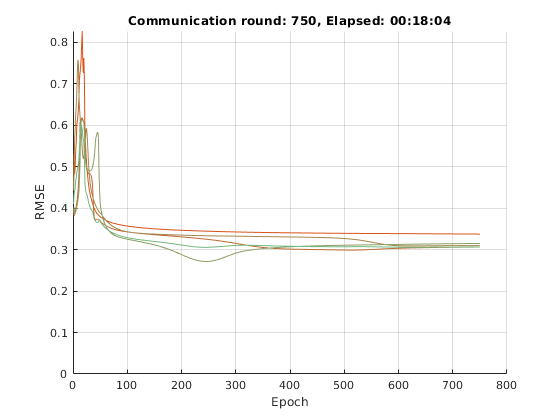

% figure
lineRMSETrain = animatedline('Color',[0.85 0.325 0.098]);
lineRMSETrain2 = animatedline('Color',[0.75 0.425 0.198]);
lineRMSETrain3 = animatedline('Color',[0.65 0.525 0.298]);
lineRMSETrain4 = animatedline('Color',[0.55 0.625 0.398]);
lineRMSETrain5 = animatedline('Color',[0.45 0.725 0.498]);

ylim([0 inf])
xlabel("Epoch")
ylabel("RMSE")
grid on

start = tic;
for round = 1:numRounds
    spmd
        % forward
        X=trainDataOfNodes(idx,featureType{labindex})';
        Y=trainDataOfNodes(idx,groundTruthIndex);
        [z1,a1,z2,a2] = forward(X,w1{labindex},w2{labindex},b1{labindex},b2{labindex});
        % update A
        if labindex == 1
            fileID = fopen('Predictions.bin','r');
            myData = fread(fileID,[numObservationsTraining numWorkers],'double');
            fclose(fileID);
            myData(idx,labindex)=a2;
            iSendDataToNextLab(myData);
        end
        myData = iRecFromPrevLab();
        if labindex ~= 1
            myData(idx,labindex)=a2;
            iSendDataToNextLab(myData);
            if labindex==numWorkers
                fileID = fopen('Predictions.bin','wb');
                fwrite(fileID, myData,'double');
                fclose(fileID);
            end
        end
        
        for batch=1:fix(numObservationsTraining/miniBatchSize)
            % Initialize Gradients
            delta1=zeros(N1,size(featureType{labindex},2)); % (10,5)
            db1=0;
            delta2=zeros(N2,N1); % (1,10)
            db2=0;

            for row=1:miniBatchSize
                % Sum of all the local predictions
                Y=trainDataOfNodes(idx((batch-1)*miniBatchSize+row),groundTruthIndex);
                X=trainDataOfNodes(idx((batch-1)*miniBatchSize+row),featureType{labindex})';
                [z1,a1,z2,a2] = forward(X,w1{labindex},w2{labindex},b1{labindex},b2{labindex});

                integrationOfPredictions=[];
                
                for s=1:numWorkers
                    if s==labindex
                        integrationOfPredictions=[integrationOfPredictions, a2];
                        
                    else
                        integrationOfPredictions=[integrationOfPredictions, myData(idx((batch-1)*miniBatchSize+row),s)];
                        
                    end
                end

                [z3,a3]=forwardServer(ones(numWorkers,1)/numWorkers,integrationOfPredictions);
                
                d3 = (a3+a2)/2-Y;
                %d3 = a2-Y;

                delta2 = delta2 + d3 * a2';   % A_{i,(t),k} =  a2          Partial Derivative    a2'
                db2= db2 + d3;

                d2 = w2{labindex}'.*d3.*dlogsig(z1,a1);   % A_{i,(t),k} =  a2             Partial Derivative w2{labindex}'.* dlogsig(z1,a1) * X'

                delta = delta1 + d2.*X';

                db1=db1+d2;
            end
            if SGDWithMomentum
                % Calculate update
                gradient1=1.0/miniBatchSize * delta1;
                gradient2=1.0/miniBatchSize * delta2;
                gradientB1=1.0/miniBatchSize * db1;
                gradientB2=1.0/miniBatchSize * db2;
        		
                %Calculate new change
                new_change1 = eta * gradient1+ momentum * change1{labindex};
                new_changeB1 = eta * gradientB1 + momentum * changeB1{labindex};
                new_change2 = eta * gradient2+ momentum * change2{labindex};
                new_changeB2 = eta * gradientB2 + momentum * changeB2{labindex};
        		% take a step
        		w1{labindex} = w1{labindex} - new_change1;
                b1{labindex} = b1{labindex} - new_changeB1;
                w2{labindex} = w2{labindex} - new_change2;
                b2{labindex} = b2{labindex} - new_changeB2;
        		% save the change
        		change1{labindex} = new_change1;
                changeB1{labindex} = new_changeB1;
        		change2{labindex} = new_change2;
                changeB2{labindex} = new_changeB2;
            else
                % Update Weights
                w1{labindex} = w1{labindex} - eta * 1.0/miniBatchSize * delta1;
                b1{labindex} = b1{labindex} - eta * 1.0/miniBatchSize * db1;
                w2{labindex} = w2{labindex} - eta * 1.0/miniBatchSize * delta2;
                b2{labindex} = b2{labindex} - eta * 1.0/miniBatchSize * db2;
            end
        end
    end
    % Get predictions of al the workers
    D = duration(0,0,toc(start),'Format','hh:mm:ss');
    Predictions=[];
    
    
    for j=1:numWorkers
        W1=cell2mat(w1{j});
      

        W2=cell2mat(w2{j});
        

        B1=cell2mat(b1{j});
        

        B2=cell2mat(b2{j});
        
        [z1,a1,z2,a2] = forward(XVal(featureType{j},:),W1,W2,B1,B2);
        
        Predictions=[Predictions; a2];

        switch j
            case 1
                addpoints(lineRMSETrain,round,sqrt(mse(a2-YVal)))
                ROUND=[ROUND;round];
                RMSE=[RMSE;sqrt(mse(a2-YVal))];
            case 2
                addpoints(lineRMSETrain2,round,sqrt(mse(a2-YVal)))
                RMSE2=[RMSE2;sqrt(mse(a2-YVal))];
            case 3
                addpoints(lineRMSETrain3,round,sqrt(mse(a2-YVal)))
                RMSE3=[RMSE3;sqrt(mse(a2-YVal))];
            case 4
                addpoints(lineRMSETrain4,round,sqrt(mse(a2-YVal)))
                RMSE4=[RMSE4;sqrt(mse(a2-YVal))];
        end
        
    end
    
    RMSEGLOBAL=[RMSEGLOBAL;sqrt(mse(mean(Predictions,1)-YVal))];
    addpoints(lineRMSETrain5,round,sqrt(mse(mean(Predictions,1)-YVal)))
    % Display the training progress of the global model.

    title("Communication round: " + round + ", Elapsed: " + string(D))
    drawnow
end

## Testing predictions

testingDatastore = parquetread(fullfile(pwd,strcat("test_fd00",num2str(FD00X),".parquet")));
RC=120;
testingDatastore.cycle=[];
testingDatastore.setting1=[];
testingDatastore.setting2=[];
testingDatastore.setting3=[];
XTest=testingDatastore{:,2:sensorsCMAPSS+1}';
YTest=testingDatastore{:,groundTruthIndex+1};
Predictions=[];
for j=1:numWorkers
    W1=cell2mat(w1{j});
      
    W2=cell2mat(w2{j});
    
    B1=cell2mat(b1{j});
    
    B2=cell2mat(b2{j});
    [z1,a1,z2,a2] = forward(XTest(featureType{j},:),W1,W2,B1,B2);
    Predictions=[Predictions; a2];
    sqrt(mse((a2-YTest)*RC))
end

ans = 32.7989

ans = 31.0198

ans = 32.1232

ans = 30.8269

sqrt(mse(120*(mean(Predictions,1)-YTest)))

ans = 30.3777

## Test and plot results

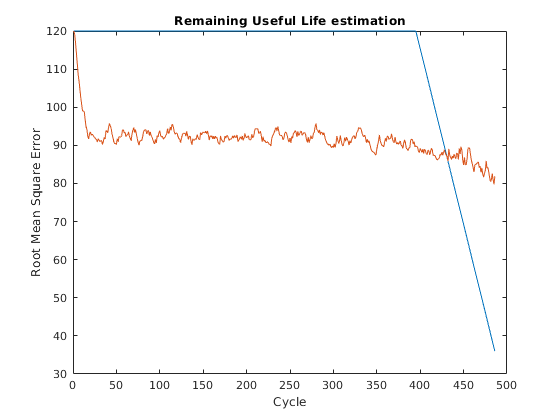

testingDatastore = parquetread(fullfile(pwd,strcat("test_fd00",num2str(FD00X),".parquet")));

rul_predicted={};
rul_truth={};

[groups,TID] = findgroups(testingDatastore.id);


TRAJECTORY=25;

WholePredictions=[];

for Node=1:numWorkers
    LocalPredictions=[];
    LocalGrounfTruth=[];
    for trajectoryID=1:length(TID)
    trajectory=testingDatastore(testingDatastore.id==TID(trajectoryID),:);
    trajectory.id=[];
    trajectory.cycle=[];
    trajectory.setting1=[];
    trajectory.setting2=[];
    trajectory.setting3=[];
    
    trajectory=trajectory{:,1:sensorsCMAPSS+1};
    XTest=trajectory(:,1:sensorsCMAPSS)';
    YTest=trajectory(:,groundTruthIndex);

    truth=YTest*RC;
    rul_truth{trajectoryID}=truth;
    
    Predictions=[];
    for j=1:Node
        W1=cell2mat(w1{j});

        W2=cell2mat(w2{j});

        B1=cell2mat(b1{j});

        B2=cell2mat(b2{j});

        [z1,a1,z2,a2] = forward(XTest(featureType{j},:),W1,W2,B1,B2);
        sqrt(mse((a2-YTest)*RC));
        Predictions=[Predictions; a2];
    end

    rul_trajectory=mean(Predictions,1);
    
    z=rul_trajectory;
    
    % Initial Parameters
    n_iter = length(rul_trajectory);
    sz = length(rul_trajectory);
    
    % Process variable
    Q = 1/209;
    
    % Allocate space for arrays
    xhat = zeros(sz);         % a posteri estiamte of x
    P = zeros(sz);            % a posteri error estimate
    xhatminus = zeros(sz);    % a priori estiamte of x
    Pminus = zeros(sz);       % a priori error estimate
    K = zeros(sz);            % gain or blending factor
    
    % Estimate of measurement variance, change to see effect
    R = 0.3^2;
    
    % Initial guesses 
    xhat(1) = truth(1)/RC;
    P(1) = 0;
    
    for k=2:n_iter
        % time update
        xhatminus(k) = xhat(k-1);
        Pminus(k) = P(k-1)+Q;
        %measurement update
        K(k) = Pminus(k)/(Pminus(k)+R);
        xhat(k) = xhatminus(k) +K(k)*(z(k)-xhatminus(k));
        P(k) = (1-K(k))*Pminus(k);
    end
    LocalGrounfTruth(size(LocalGrounfTruth,2)+1:size(LocalGrounfTruth,2)+size(YTest))=YTest;% To save array of ground truth
    LocalPredictions(size(LocalPredictions,2)+1:size(LocalPredictions,2)+size(xhat(:,1)',2))=xhat(:,1)'; % To save i matrix with predictions of parties
    xhat = xhat(:,1)*RC;
    
    rul_predicted{trajectoryID}=xhat;

    if trajectoryID==TRAJECTORY
        clf
        x=1:length(z);
        %y=z*RC;
        y=truth';
        y=vertcat(y,xhat');
        plot(x,y)
        title('Remaining Useful Life estimation');
        xlabel('Cycle');
        ylabel('Root Mean Square Error');
        %labels = {'Ground Thruth', 'Estimated', 'Filtered'};
        hold on
        %text(x(ceil(length(x)/2)).*ones(length(labels),1),y(:,ceil(length(x)/2)),labels);
    end

    end
    if Node==1
        WholePredictions=[WholePredictions,LocalGrounfTruth'];
    end
    WholePredictions=[WholePredictions,LocalPredictions'];
end

## Save predictions 

filename = 'VFL_FD004_4Nodes_MLP_10.xlsx';
writematrix(WholePredictions,filename,'Sheet',1)

RootMeanSquaredError = 28.6819

MeanAbsoluteError = 26.4016

## Forward and Activation Functions

function [z1,a1,z2,a2] = forward(X,w1,w2,b1,b2)

%Input Layer
z1=w1*X+b1;
a1=logsig(z1);

%Hidden Layer
z2=w2*a1+b2;
a2=max(0,z2);
end

function [z1,a1] = forwardServer(X,w1)

%Input Layer
z1=w1*X;
a1=z1;
end


## Sending Messages between Workers

function iSendDataToNextLab(mydata)
nextlab = mod(labindex,  numlabs) + 1;
labSend(mydata, nextlab);
end
%--------------------------------------------------------------------------
function result = iRecFromPrevLab()
prevlab = mod(labindex - 2,  numlabs) + 1;
result = labReceive(prevlab);
end
